# Dual quaternion kinematics and dynamics

並進と回転を別々にといたものと比較

clc
clear


## parameters and initial condtioin

global m MOI mu
MOI = diag([100, 150, 200]);
m = 100;

const = orbitConst;
mu = const.GE;

% trivial motion
% iniPos = [0 0 0];
% iniVelI = [1 1 0]; % @inertial frame


### orbital motion


$$\oe = [a,e,i,\Omega,\omega,f]
$$


### using TLE

tle = readTLE('JCSAT2.txt', const);
oe = tle.oe;


### or manual setting

% oe = [const.RE+800, 0.0, deg2rad(0), 0, 0, 0];

[iniPos, iniVelI] = oe2rv(oe, 1, const.GE);
n = sqrt(const.GE / oe(1)^3);
T = 2 * pi / n;

iniQ = rand(1,4);
iniQ = iniQ ./ norm(iniQ);

iniW = [0.0, 0.001, 0.003];

iniDQ = pos2dq(1, 4, iniPos, iniQ)

iniDQ = 1.0e+04 *

   0.000018148737341   0.000072391210217   0.000012077496956   0.000065454335865   0.854136508969158   1.112874006485101   0.355091295073145  -1.533166718618963


iniVelB = qRotation(4, iniVelI, iniQ); %@body-fixed frame
dualVel = [iniW, 0, iniVelB, 0];

option = odeset('RelTol', 1e-10, 'AbsTol', 1e-10);
tspan = 0:2:T*1;
t_ = tspan;

## dual quaternion

tic
[t_, x_] = ode45(@(t,x) dqEOM(t,x), tspan, [iniDQ dualVel], option);
% x_ = ode4(@dqEOM, tspan, [iniDQ dualVel]');
toc

経過時間は 12.545912 秒です。


### data handling

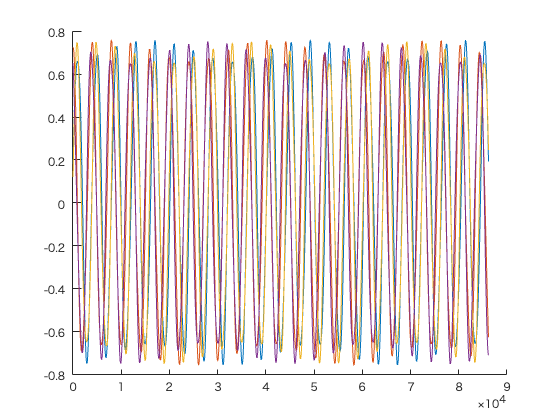

dq = x_(:,1:8);
dualVel = x_(:,9:16);

[r, q] = dq2pos(1, 4, dq);

figure, hold on;
plot(t_, dq(:,1));
plot(t_, dq(:,2));
plot(t_, dq(:,3));
plot(t_, dq(:,4));

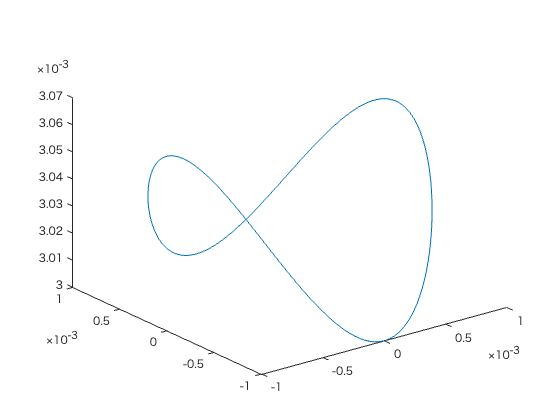


figure
plot3(dualVel(:,1), dualVel(:,2), dualVel(:,3))

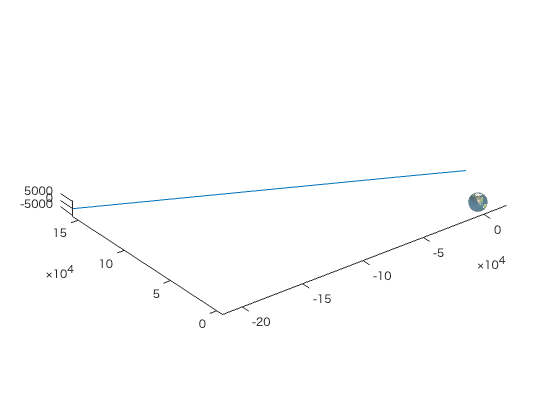


figure
plot3(r(:,1), r(:,2), r(:,3)), hold on
drawEarth(0, 0.7, const);
axis equal

## decoupled motion

iniX = [iniQ, iniW, iniPos, iniVelI];
tic
[t_, x_] = ode45(@(t,x) decEOM(t,x), tspan, iniX, option);
% x_ = ode4(@decEOM, tspan, iniX');
toc

経過時間は 0.359682 秒です。



decR = x_(:,8:10);


### pseudo true motion

iniX = [iniQ, iniW, iniPos, iniVelI];
option = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
tic
[t_, true_] = ode89(@(t,x) decEOM(t,x), tspan, iniX, option);

toc

経過時間は 0.284553 秒です。



trueR = true_(:,8:10);


## compare

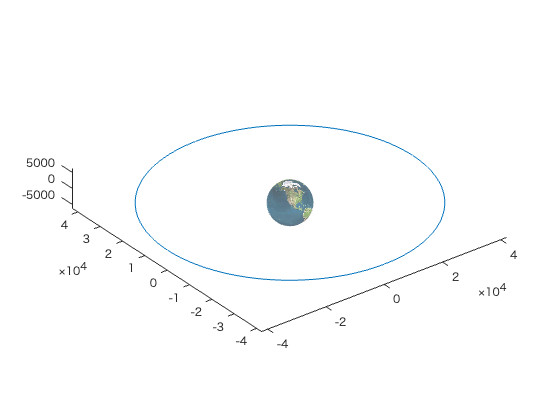

figure
plot3(decR(:,1), decR(:,2), decR(:,3)), hold on
drawEarth(0, 0.7, const);
axis equal

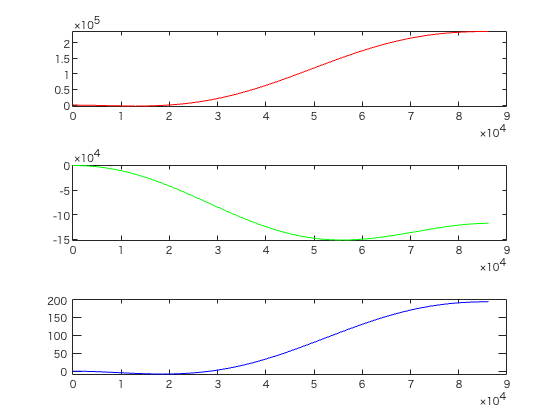


figure
tiledlayout(3,1),nexttile
plot(t_, trueR(:,1) - r(:,1), 'r'),nexttile
plot(t_, trueR(:,2) - r(:,2), 'g'),nexttile
plot(t_, trueR(:,3) - r(:,3), 'b')

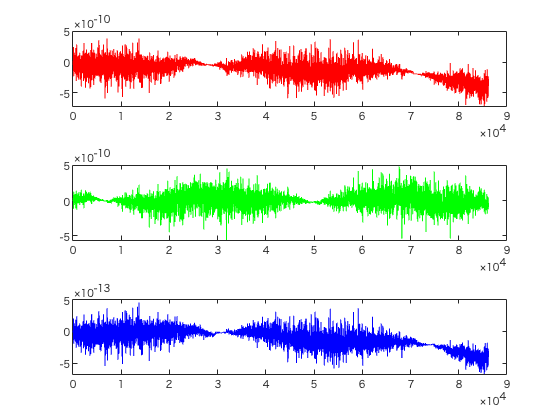


figure
tiledlayout(3,1),nexttile
plot(t_, trueR(:,1) - decR(:,1), 'r'),nexttile
plot(t_, trueR(:,2) - decR(:,2), 'g'),nexttile
plot(t_, trueR(:,3) - decR(:,3), 'b')